# This is the Main code

#### Initialization of Dynamical system parameters

m = 1;     % mass
k = 1;     % stiffness
c = 0.02;  % damping coeffient 
dt = 0.01; % timestep
t = 0:dt:10; 

'data_constant' has response data generated corresponding to constant $\text{force} = 1$

'data_sin' has response data generated corresponding to $\text{force}=\sin(\pi  t)$ 

Data = importdata('data_sin.mat'); 

#### **Defined Dynamical system**

**Here the external force on the dynamical system is not direct on it. So D = 0**

Ac = [0 1; -k/m -c/m];
Bc = [0; 1/m];
C = [-k/m -c/m];

sysc = ss(Ac,Bc,C,[]);
sysd = c2d(sysc, dt);


extra_params.A = sysd.A ;
extra_params.B = sysd.B ;
extra_params.C = C;


#### Setting hyperparameters value 

alpha = hyperparameter('alpha');
max_episode = hyperparameter('max_episode');
max_steps = hyperparameter('max_steps');
gamma = hyperparameter('gamma');
eval = hyperparameter('eval');
eval_max_steps = hyperparameter('eval_max_steps');

#### 'phi' and 'theta' value are initialized or imported based on whether the agent is going to be trained or evaluated

if eval == false   
phi = hyperparameter('phi'); % initialize
theta = hyperparameter('theta'); % initialize
else
phi = importdata('phi.mat');
theta = importdata('theta.mat');
end

## Training of the agent:

#### To evaluate this algorithm make 'eval == false' in hyperparameters file


if eval == false
for i = 1:max_episode

%x_0 = hyperparameter('displacement'); % initial displacment

%sigma = 1; % initial variance

totalr = 0;          % total reward initialized
start_point = randi([1,eval_max_steps - max_steps],1);  % deciding start point of episode randomly
%X = Data(:,3);
state = [Data(start_point,3),Data(start_point,4),Data(start_point,1),Data(start_point,2)]; % decide (displacement,velocity, acceleration, force) 

for j = start_point:max_steps + start_point - 1
learn = false;
action = policy(state,learn,[],[],gamma,phi,theta,[],alpha);
[reward, next_state]= env(action,extra_params,state,j,Data);


%% Update parameters(theta) of policy i.e Actor model
learn = true;
theta = policy(state,learn,reward,next_state,gamma,phi,theta,action,alpha);

%% Update parameters(phi) of value function i.e Critic model
grad = grad_Critic(state,next_state,phi,reward,gamma);
phi = phi - alpha*grad;

state = next_state;

totalr = totalr + reward; % total reward (totalr) is not used for training the agent
end
alpha = alpha*.9;
%disp(totalr); % done to get to know whether the agent is getting  trained correctly 


end
save('phi.mat','phi');
save('theta.mat','theta');
end

## Evaluataion of the agent:

#### To evaluate this algorithm make 'eval == true' in hyperparameters file

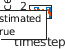


if eval == true

    phi = importdata('phi.mat');
    theta = importdata('theta.mat');
    
for i = 1:1

%x_0 = hyperparameter('displacement'); % initial displacment
start_point = 1;
%sigma = 1; % initial variance
state = [Data(start_point,3),Data(start_point,4),Data(start_point,1),Data(start_point,2)]; % decide (displacement,velocity, acceleration, force) 


for j = 1:eval_max_steps
learn = false;
action = policy(state,learn,[],[],gamma,phi,theta,[],alpha);
[reward, next_state]= env(action,extra_params,state,j,Data);

state = next_state;

%disp(reward); % 
r(j,:)=reward; % immediate reward stored
a(j,:)=action; % action(force) taken stored
end

end

%% Plot of the result

u = Data(1:eval_max_steps,2)';
x = 1:1:eval_max_steps;
plot(x,a);
hold on
plot(x,u);
xlabel('timestep');
ylabel('force');
legend({'Estimated','True'});
end